clear
clc;

Інформація про файл

info = audioinfo('audio.wav');  
disp(info);

             Filename: 'D:\university\5\ma_labs\ma_lab6_2\audio.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8000
         TotalSamples: 40000
             Duration: 5
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16



Зчитуєм аудіо з файлу

[audio, Fs] = audioread('audio.wav');
t = length(audio) / Fs; %time

Оригінаьне аудіо

sound(audio, Fs);
pause(t)

Прискорене аудіо

sound(audio, Fs * 2);
pause(t / 2)

Уповільнене аудіо

sound(audio, Fs / 2);

Графік сигналу

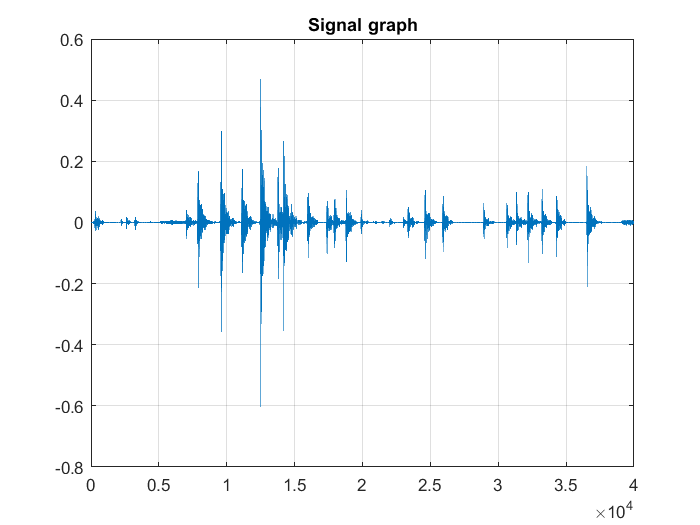

plot(audio); 
title("Signal graph");
grid on;

Спектрограма 

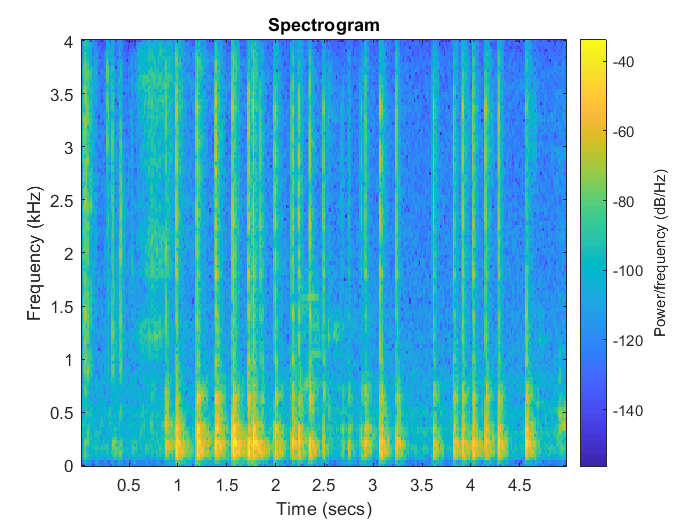

spectrogram(audio, 256, 128, [], Fs, 'yaxis');
title('Spectrogram');

Амплітудний спектр

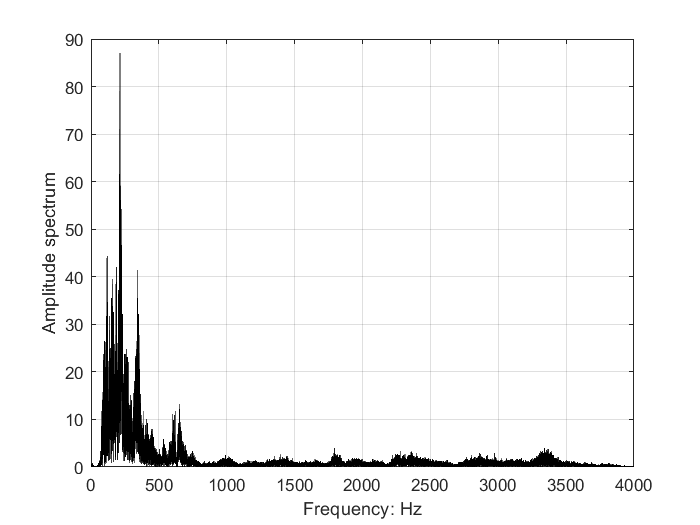

aspec = abs(fft(audio)); % Для кожного сегмента обчислюється спектр
aspec = aspec(1 : end / 2); %бо графік симетричний
afreq = (Fs / 2) * (1:length(aspec)) / length(aspec);
plot(afreq, aspec, 'k'); 
xlabel ('Frequency: Hz'); ylabel ('Amplitude spectrum');
grid on;

Фазовий спектр

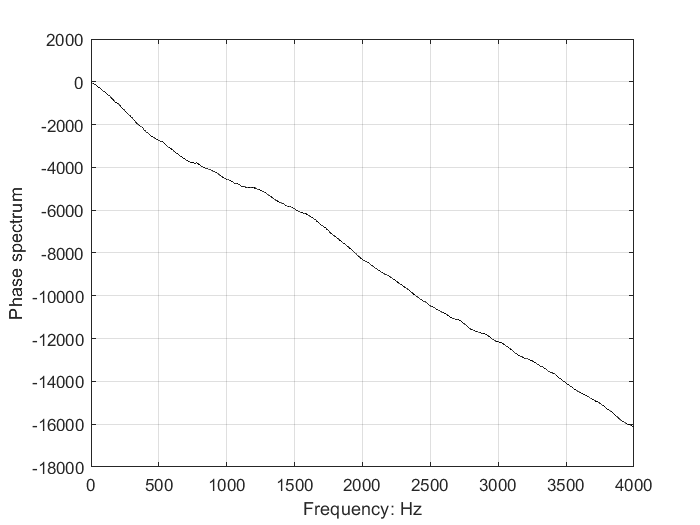

fspec = phase (fft(audio)); % Для кожного сегмента обчислюється спектр
fspec = fspec (1:end/2); 
ffreq = (Fs / 2) * (1:length(fspec)) / length(fspec);
plot(ffreq, fspec, 'k'); 
xlabel ('Frequency: Hz'); ylabel ('Phase spectrum');
grid on;